# Independent Component Analysis of whole brain using Aya's EEG dataset: Similarity Analysis

clear;

% ===============================================
% Compute ICA for each subject × condition × subtype
% ===============================================

clear; clc;

%% 1) Set your input/output roots
if exist('H:\', 'dir')         % Computer 1
    input_root  = 'C:\Users\sinad\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results\ICA\';
    output_root = 'C:\Users\sinad\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results\ICA\';
elseif exist('G:\', 'dir')     % Computer 2
    input_root  = 'C:\Users\sdabiri\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results\ICA\';
    output_root = 'C:\Users\sdabiri\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results\ICA\';
else
    error('Unknown system. Please adjust your paths.');
end

conditions = {'BLA','BLT', 'P1', 'P2', 'P3'}; %
subjects = {'BOS2'};%, 'BOS3', 'BOS5', 'BOS6', 'BOS7', 'BOS8', 'BOS9', 'BOS10', ...
    % 'BOS11', 'BOS12', 'BOS13', 'BOS15', 'BOS16', 'BOS17'

## Define for each "top‐down” condition the two subtype labels and the sheet names

subtypeInfo.P2.labels    = {'A','B'};
subtypeInfo.P2.sheetsA   = 'Audio onset with 500 ms tactile';
subtypeInfo.P2.sheetsB   = 'Audio onset with 2000 ms tactil';

subtypeInfo.P3.labels    = {'A','B'};
subtypeInfo.P3.sheetsA   = 'Audio onset with 500 ms tactile';
subtypeInfo.P3.sheetsB   = 'Audio onset with missing tactil';

% Start the parallel pool once at the beginning
try
    poolobj = gcp('nocreate'); % Get current parallel pool without creating one
    if isempty(poolobj)
        poolobj = parpool(); % Create a parallel pool with default settings
    end
catch err
    warning('Could not create parallel pool');
    warning('Running in serial mode instead');
end

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 8 workers.


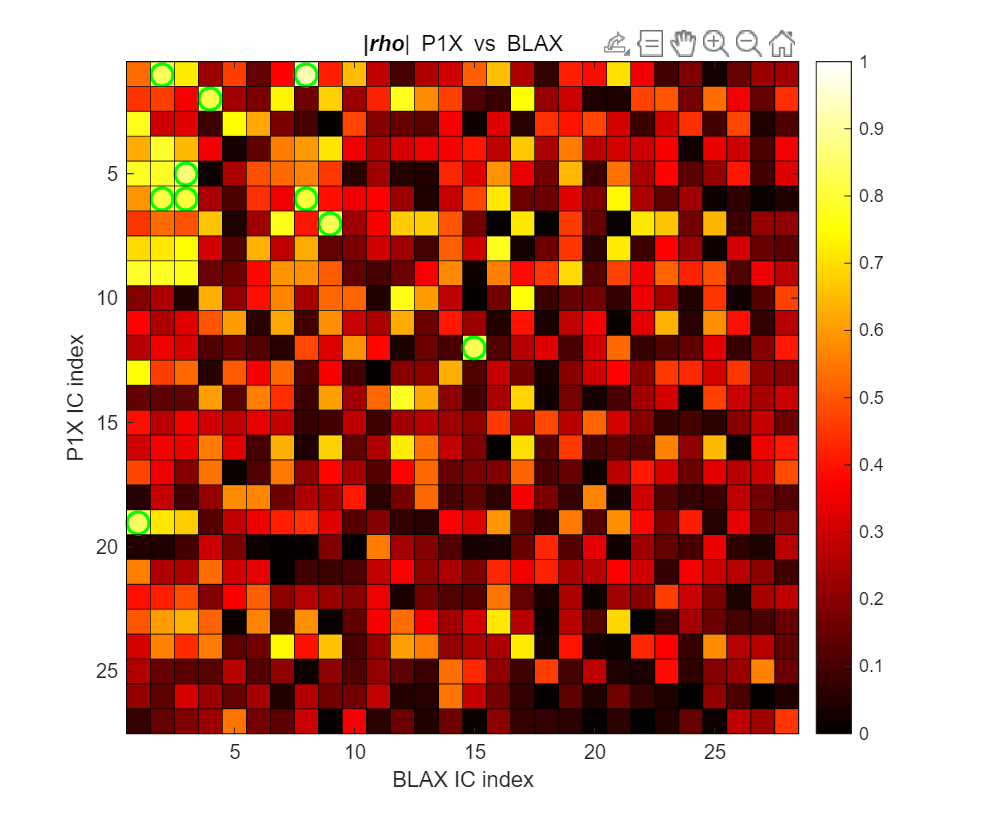

  • Matched 10 pairs ≥ 0.80 for P1X vs BLAX


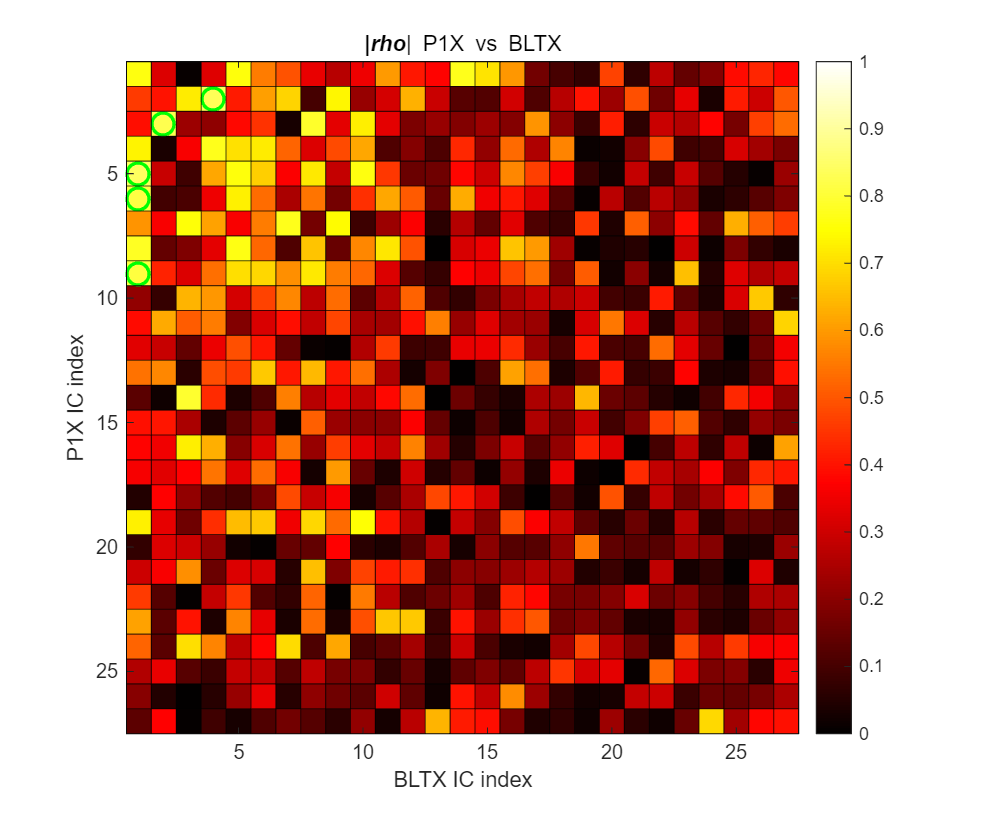

  • Matched 5 pairs ≥ 0.80 for P1X vs BLTX


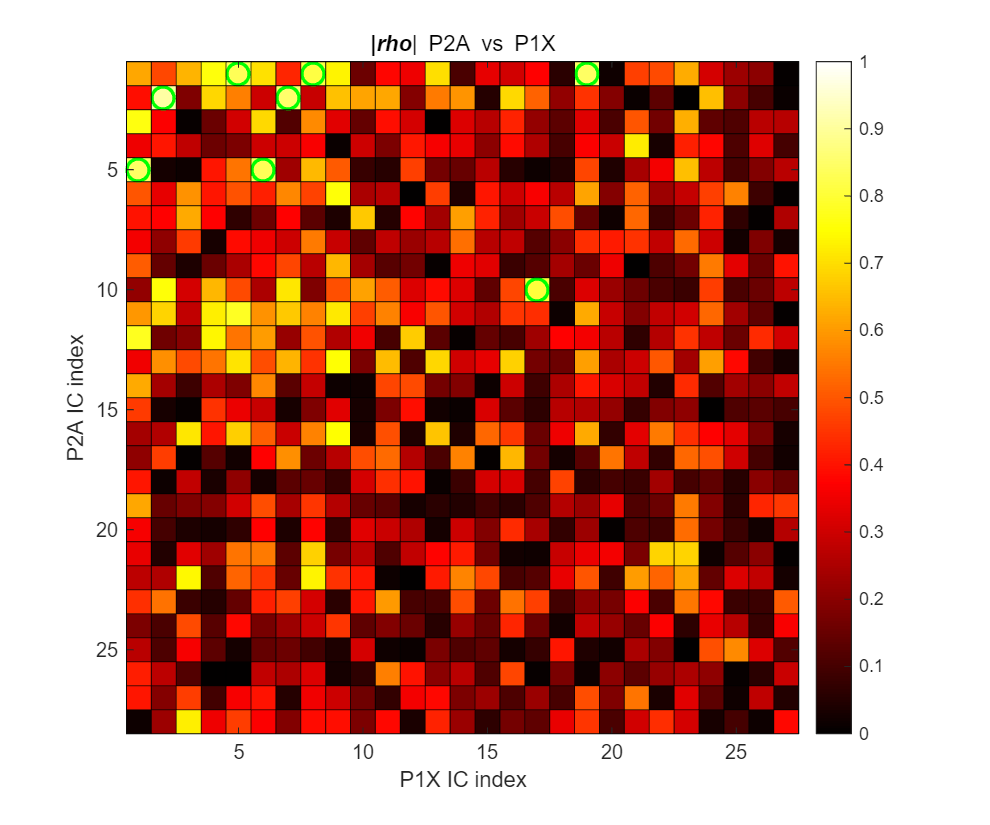

  • Matched 8 pairs ≥ 0.80 for P2A vs P1X


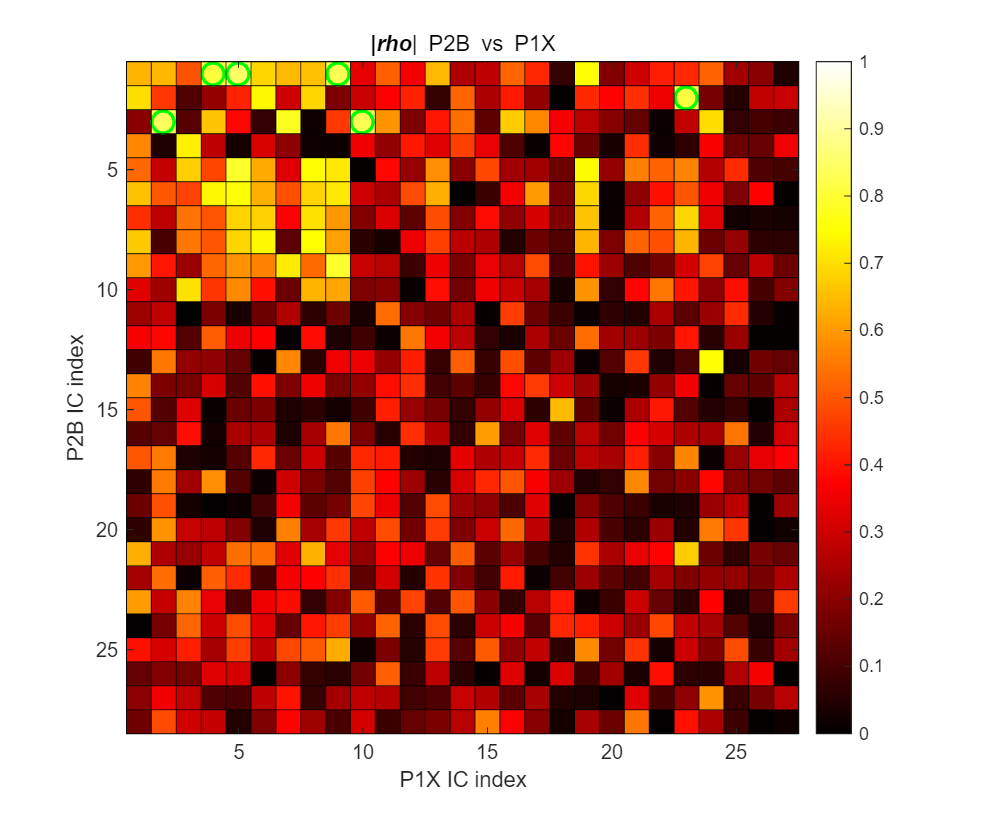

  • Matched 6 pairs ≥ 0.80 for P2B vs P1X


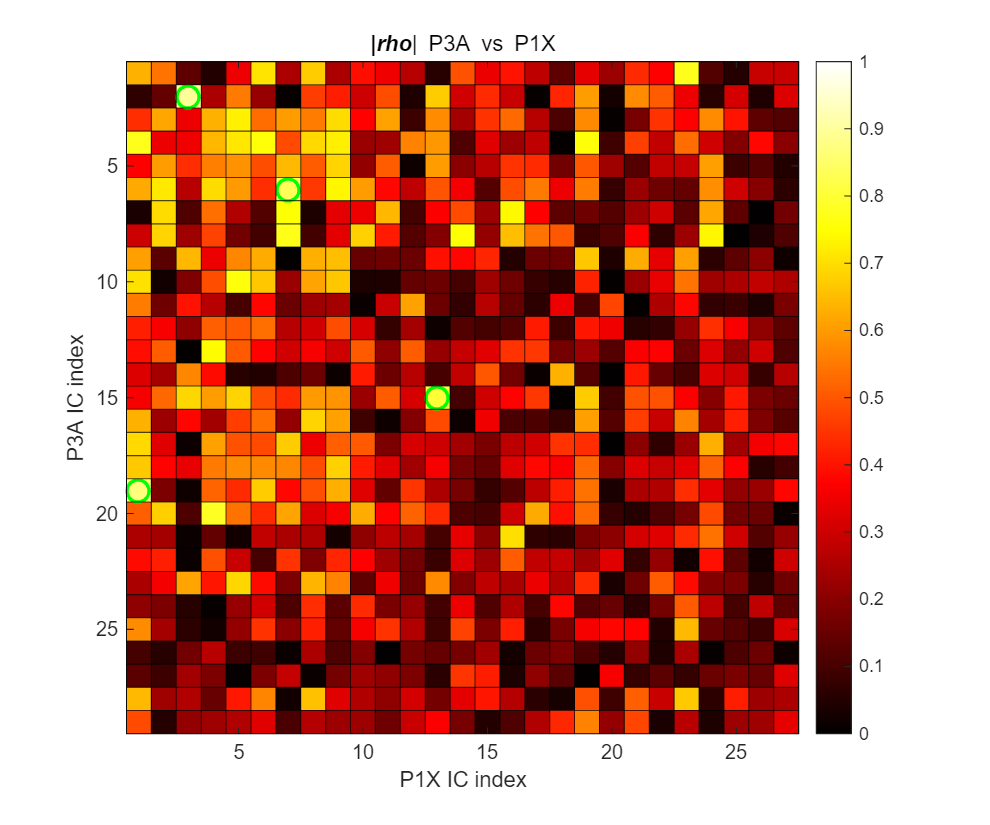

  • Matched 4 pairs ≥ 0.80 for P3A vs P1X


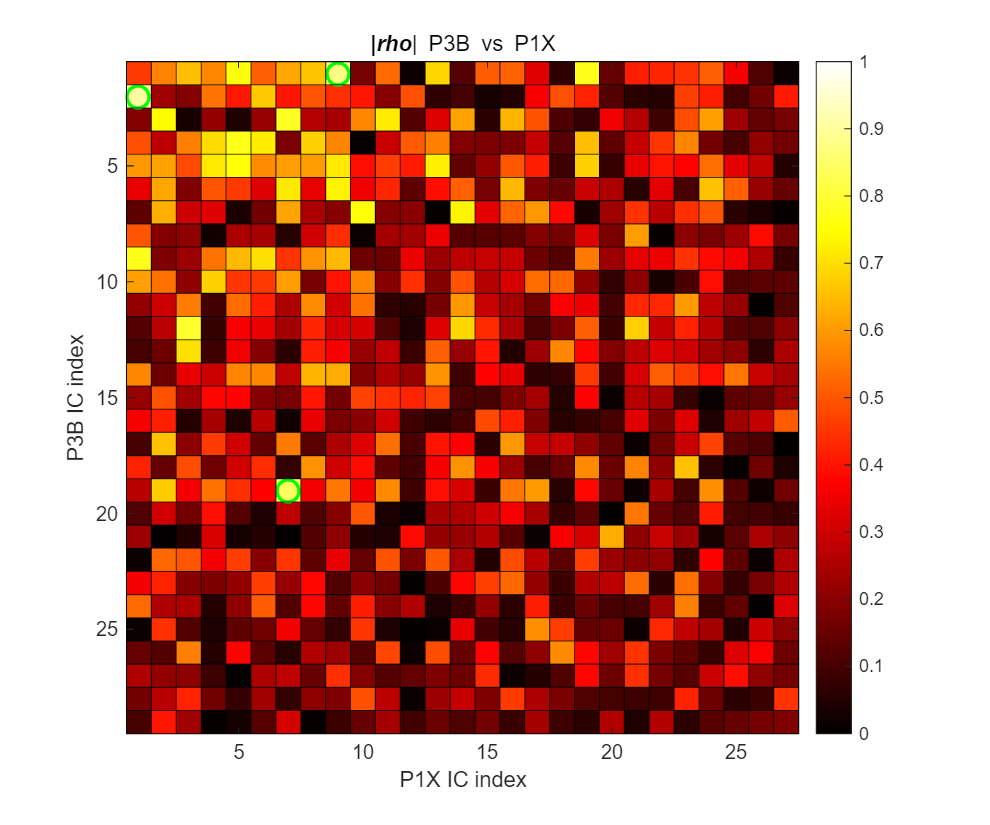

  • Matched 3 pairs ≥ 0.80 for P3B vs P1X


for j = 1:length(subjects)
    subject = subjects{j};
    match_ICs_across_conditions(subject, input_root);

end

function match_ICs_across_conditions(subject, input_root)
% MATCH_ICS_ACROSS_CONDITIONS  Correlate ICA scalp maps across your conditions
%
%   match_ICs_across_conditions('BOS2', ...
%        'C:\…\temporal_criticality_of_latent_results\ICA\')
%
%   Assumes you have saved each condition/subtag’s EEGsub in:
%     input_root\<subject>\<condition>\<subtag>\EEG_ICA.mat

  %% 1) Define which pairs to compare
  comparisons = { ...
    {'P1','X', 'BLA','X'};    % P1 vs BLA
    {'P1','X', 'BLT','X'};    % P1 vs BLT
    {'P2','A', 'P1','X'};     % P2A vs P1
    {'P2','B', 'P1','X'};     % P2B vs P1
    {'P3','A', 'P1','X'};     % P3A vs P1
    {'P3','B', 'P1','X'};     % P3B vs P1
  };

  for k = 1:numel(comparisons)
    C = comparisons{k};
    cond1 = C{1}; sub1 = C{2};
    cond2 = C{3}; sub2 = C{4};

    % Build paths
    p1 = fullfile(input_root, subject, cond1, sub1, 'EEG_ICA.mat');
    p2 = fullfile(input_root, subject, cond2, sub2, 'EEG_ICA.mat');
    if ~exist(p1,'file') || ~exist(p2,'file')
      warning('Missing %s or %s — skipping', p1, p2);
      continue;
    end

    % Load
    tmp = load(p1,'EEGsub'); EEG1 = tmp.EEGsub;  clear tmp;
    tmp = load(p2,'EEGsub'); EEG2 = tmp.EEGsub;  clear tmp;

    % Extract mixing matrices
    A1 = EEG1.icawinv;   % [nCh × nIC1]
    A2 = EEG2.icawinv;   % [nCh × nIC2]
    nIC1 = size(A1,2);
    nIC2 = size(A2,2);

    %% 2) Compute abs-correlation matrix
    corrMat = zeros(nIC1,nIC2);
    for iIC = 1:nIC1
      for jIC = 1:nIC2
        corrMat(iIC,jIC) = abs( corr( A1(:,iIC), A2(:,jIC) ) );
      end
    end

    %% 3) Threshold & (optional) one-to-one matching
    thresh = 0.8;
    [I,J] = find(corrMat >= thresh);
    % Optional: for a 1:1 global assignment via Hungarian:
    % cost = 1-corrMat;
    % [pairs, ~] = matchpairs(cost, Inf, 'min'); 

    %% 4) Plot
    figure('Name',sprintf('%s: %s%s vs %s%s',subject,cond1,sub1,cond2,sub2),...
           'NumberTitle','off','Position',[100 100 600 500]);
    imagesc(corrMat, [0 1]);
    axis tight; axis square;
    xlabel(sprintf('%s%s IC index',cond2,sub2));
    ylabel(sprintf('%s%s IC index',cond1,sub1));
    title(sprintf('|\\itrho\\rm| %s%s vs %s%s', cond1,sub1, cond2,sub2));
    colorbar; colormap('hot');

    hold on;
    % mark all pairs above threshold
    plot(J, I, 'go', 'MarkerSize',10, 'LineWidth',1.5);

    % (optional) mark one-to-one matches in a different color:
    % for p = 1:size(pairs,1)
    %   plot(pairs(p,2), pairs(p,1), 'bx', 'MarkerSize',12, 'LineWidth',2);
    % end

    % Draw threshold lines
    yline(0.5 + (0:nIC1),'k-','LineWidth',0.5);
    xline(0.5 + (0:nIC2),'k-','LineWidth',0.5);

    hold off;

    % Save figure
    outfig = fullfile(input_root, subject, ...
                      sprintf('match_%s%s_vs_%s%s.png', ...
                              cond1,sub1,cond2,sub2));
    saveas(gcf, outfig);
    % close(gcf);

    fprintf('  • Matched %d pairs ≥ %.2f for %s%s vs %s%s\n', ...
            numel(I), thresh, cond1, sub1, cond2, sub2);
  end
end


% % Project 4D data back into IC space: This gives you the IC activations as a 4D tensor, preserving trial and condition structure.
% X_2D = reshape(X, ch, []);
% IC_activations = W * X_2D;  % W is ICA unmixing matrix
% IC_tensor = reshape(IC_activations, size(W,1), time, trials, conds);